Import Dataset

clear
clc
clf
load('ECG_database 2022-10-05 13_54_01.mat');

n = 5000;
t = 0:0.002:10-0.002;
fs = 500;
f = (0:n-1)*(fs/n);
fshift = (-n/2:n/2-1)*(fs/n);

**Data previewing**

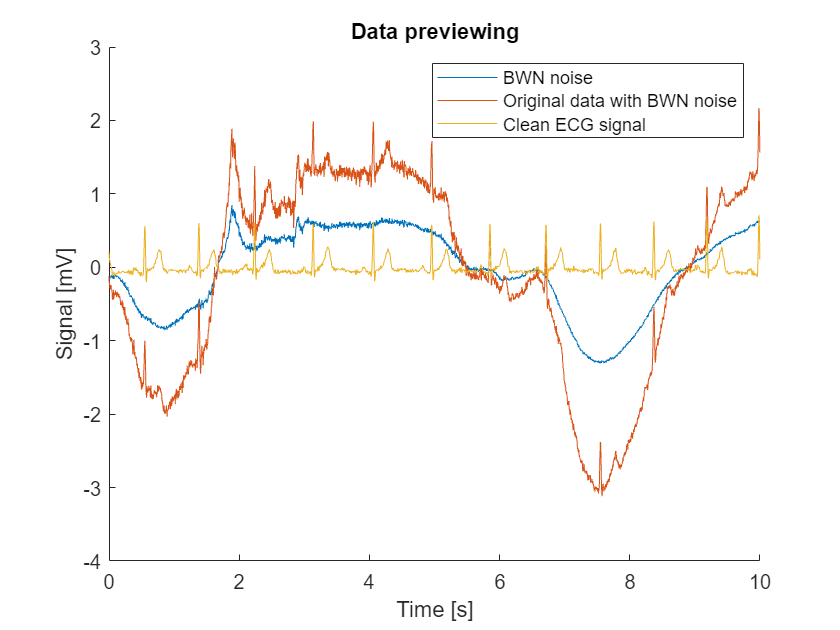

figure
hold on
plot(t,bwn/200)
plot(t,BWN_data/200)
plot(t,Data1/200)
hold off

title('Data previewing');
legend('BWN noise',...
    'Original data with BWN noise', 'Clean ECG signal',...
    'Location','NorthEast');
xlabel('Time [s]')
ylabel('Signal [mV]')

**Adaptive filter RLS LMS nLMS for BWN denoising**

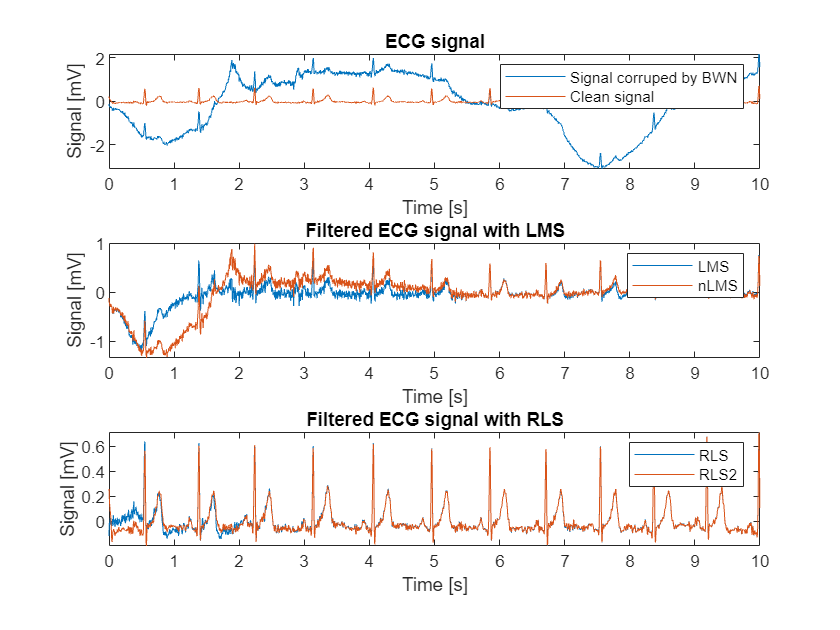

d=BWN_data/200;
x=bwn/200;

% RLS
rlsFilt = dsp.RLSFilter;
[noise_Rls,e_Rls] = rlsFilt(x, d);

[noise_Rls2,e_Rls2] = rlsFilt(x, d);

% LMS
lms = dsp.LMSFilter(12,'Method','LMS','StepSize',0.001);
[noise_Lms,e_Lms,wts] = lms(x',d');

%Normalised LMS
nlms = dsp.LMSFilter(12,'Method','Normalized LMS','StepSize',0.001);
[noise_nLms,e_nLms] = nlms(x',d');


figure
%     subplot(5,1,1);
% plot( t, d)
% title ('ECG signal corrupted by BWN')
%     subplot(5,1,2);
% plot( t, e_Lms)
% title ('Filtered ECG signal with LMS')
%     subplot(5,1,3);
% plot( t, e_nLms)
% title ('Filtered ECG signal with Normalised LMS')
%     subplot(5,1,4);
% plot( t, e_Rls)
% title ('Filtered ECG signal with RLS')
%     subplot(5,1,5);
% plot( t, e_Rls)
% title ('Filtered ECG signal with quadratic RLS')

clf
    subplot(3,1,1);
plot( t, d, t, Data1/200)
title ('ECG signal')
legend('Signal corruped by BWN', 'Clean signal')
xlabel('Time [s]')
ylabel('Signal [mV]')
    subplot(3,1,2);
plot( t, e_Lms, t, e_nLms)
title ('Filtered ECG signal with LMS')
xlabel('Time [s]')
ylabel('Signal [mV]')
legend('LMS', 'nLMS')
    subplot(3,1,3);
plot( t, e_Rls,t,e_Rls2)
title ('Filtered ECG signal with RLS')
legend('RLS', 'RLS2')
xlabel('Time [s]')
ylabel('Signal [mV]')

**Data Analysis ---  PSD plot**

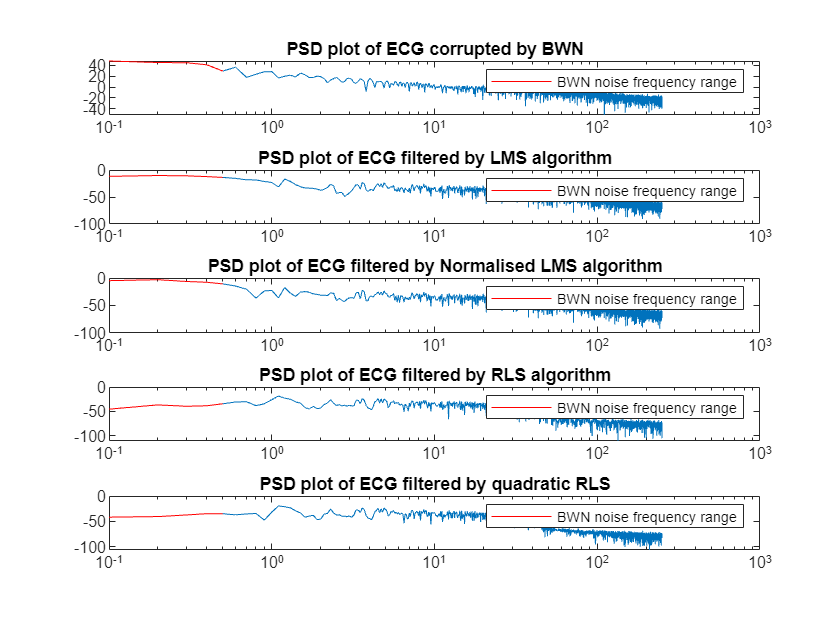

figure

[Psd_bwn,F] = periodogram(bwn,[],length(bwn),fs);
subplot(5,1,1)
semilogx(F,10*log10(Psd_bwn))
hold on
semilogx(F(0.5<F<0.6),10*log10(Psd_bwn(0.5<F<0.6)),'r')
hold off
legend('','BWN noise frequency range')
title('PSD plot of ECG corrupted by BWN')

[Psd_bwn,F] = periodogram(e_Lms,[],length(e_Lms),fs);
subplot(5,1,2)
semilogx(F,10*log10(Psd_bwn))
hold on
semilogx(F(0.5<F<0.6),10*log10(Psd_bwn(0.5<F<0.6)),'r')
hold off
legend('','BWN noise frequency range')
title('PSD plot of ECG filtered by LMS algorithm')

[Psd_bwn,F] = periodogram(e_nLms,[],length(e_nLms),fs);
subplot(5,1,3)
semilogx(F,10*log10(Psd_bwn))
hold on
semilogx(F(0.5<F<0.6),10*log10(Psd_bwn(0.5<F<0.6)),'r')
hold off
legend('','BWN noise frequency range')
title('PSD plot of ECG filtered by Normalised LMS algorithm')

[Psd_bwn,F] = periodogram(e_Rls,[],length(e_Rls),fs);
subplot(5,1,4)
semilogx(F,10*log10(Psd_bwn))
hold on
semilogx(F(0.5<F<0.6),10*log10(Psd_bwn(0.5<F<0.6)),'r')
hold off
legend('','BWN noise frequency range')
title('PSD plot of ECG filtered by RLS algorithm')

[Psd_bwn,F] = periodogram(e_Rls2,[],length(e_Rls2),fs);
subplot(5,1,5)
semilogx(F,10*log10(Psd_bwn))
hold on
semilogx(F(0.5<F<0.6),10*log10(Psd_bwn(0.5<F<0.6)),'r')
hold off
legend('','BWN noise frequency range')
title('PSD plot of ECG filtered by quadratic RLS')

**Data Analysis ---  Spectrogram plots**

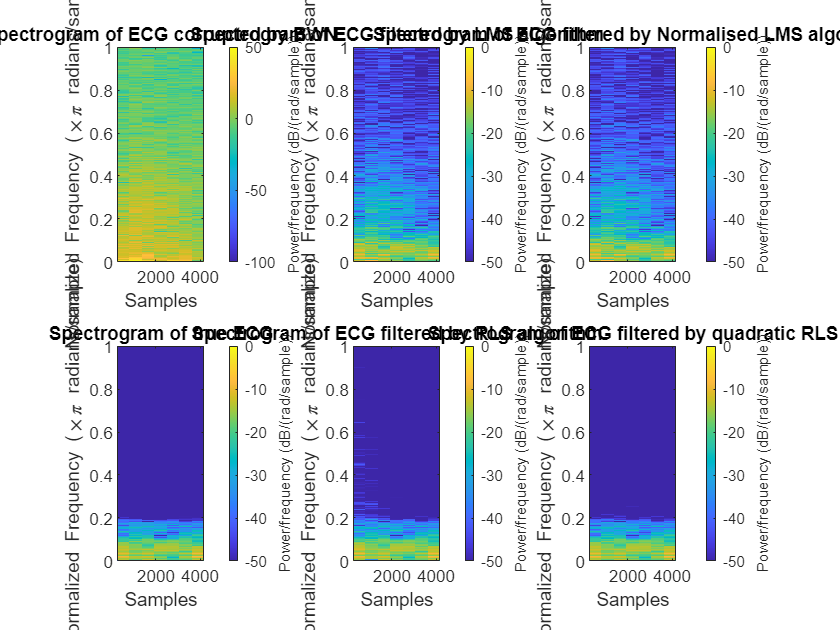

figure
subplot(2,3,1)
s1 = spectrogram(bwn);
spectrogram(bwn,'yaxis')
title('Spectrogram of ECG corrupted by BWN')
clim([-100, 50])


subplot(2,3,2)
s2 = spectrogram(e_Lms);
spectrogram(e_Lms,'yaxis')
title('Spectrogram of ECG filtered by LMS algorithm')
clim([-50, 0])

subplot(2,3,3)
s3 = spectrogram(e_nLms);
spectrogram(e_Lms,'yaxis')
title('Spectrogram of ECG filtered by Normalised LMS algorithm')
clim([-50, 0])

subplot(2,3,4)
s4 = spectrogram(Data1/200);
spectrogram(Data1/200,'yaxis')
title('Spectrogram of true ECG')
clim([-50, 0])

subplot(2,3,5)
s4 = spectrogram(e_Rls);
spectrogram(e_Rls,'yaxis')
title('Spectrogram of ECG filtered by RLS algorithm')
clim([-50, 0])

subplot(2,3,6)
s5 = spectrogram(e_Rls2);
spectrogram(e_Rls2,'yaxis')
title('Spectrogram of ECG filtered by quadratic RLS')
clim([-50, 0])

**SNR improvement**

% x = bwn/200
SNR_nLms1=snr(e_nLms',e_nLms'-Data1/200) - snr(Data1/200,d-Data1/200)

SNR_nLms1 = 21.5696

SNR_Lms1=snr(e_Lms',e_Lms'-Data1/200) - snr(Data1/200,d-Data1/200)

SNR_Lms1 = 22.3143

SNR_Rls1=snr(e_Rls,e_Rls-Data1/200) - snr(Data1/200,d-Data1/200)

SNR_Rls1 = 33.3811

SNR_Rls2=snr(e_Rls2,e_Rls2-Data1/200) - snr(Data1/200,d-Data1/200)

SNR_Rls2 = 47.9088

**RMSE**

err_nLms1 = sqrt(immse(Data1/200,e_nLms'))

err_nLms1 = 0.3758

err_Lms1 = sqrt(immse(Data1/200,e_Lms'))

err_Lms1 = 0.2179

err_Rls1 = sqrt(immse(Data1/200,e_Rls))

err_Rls1 = 0.0286

err_Rls2 = sqrt(immse(Data1/200,e_Rls2))

err_Rls2 = 0.0053

**PRD**

prd_nLms1 = prd(Data1/200,e_nLms')

prd_nLms1 = 327.1834

prd_Lms1 = prd(Data1/200,e_Lms')

prd_Lms1 = 189.6942

prd_Rls1 = prd(Data1/200,e_Rls)

prd_Rls1 = 24.8851

prd_Rls2 = prd(Data1/200,e_Rls2)

prd_Rls2 = 4.6372

**Convergence speed (Error magntude vs Sample index)**

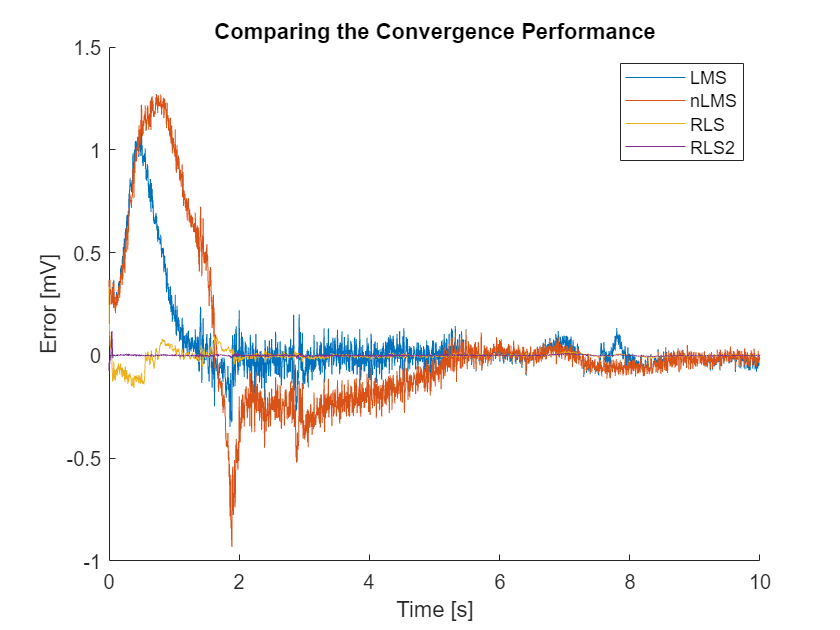

figure
hold on
plot(t, Data1/200-e_Lms');
plot(t, Data1/200-e_nLms');
plot(t, Data1/200-e_Rls);
plot(t, Data1/200-e_Rls2);

% plot(abs(Data1/200-e_Rls))
% plot(abs(Data1/200-e_Lms'))
% plot(abs(Data1/200-e_nLms'))

title('Comparing the Convergence Performance');
legend('LMS','nLMS','RLS','RLS2', 'Location', 'NorthEast');
xlabel('Time [s]')
ylabel('Error [mV]')

Defined Function

function [y] = prd(a,b)
y = 100*sqrt(((a-b)*(a-b)')./(a*a'));
end